#  Definición de derivados 

[⇦ Menú principal](matlab:open('MainMenu.mlx'))

 ¿Cuánto tiempo tienes para tomar el café antes de que se enfríe demasiado? ¿Qué distancia recorrerá una pelota antes de tocar el suelo? ¿Mi sofá cabrá por el pasillo hasta mi apartamento? Muchas interacciones cotidianas pueden describirse mediante funciones, y estas funciones pueden analizarse estudiando sus tasas de cambio. 

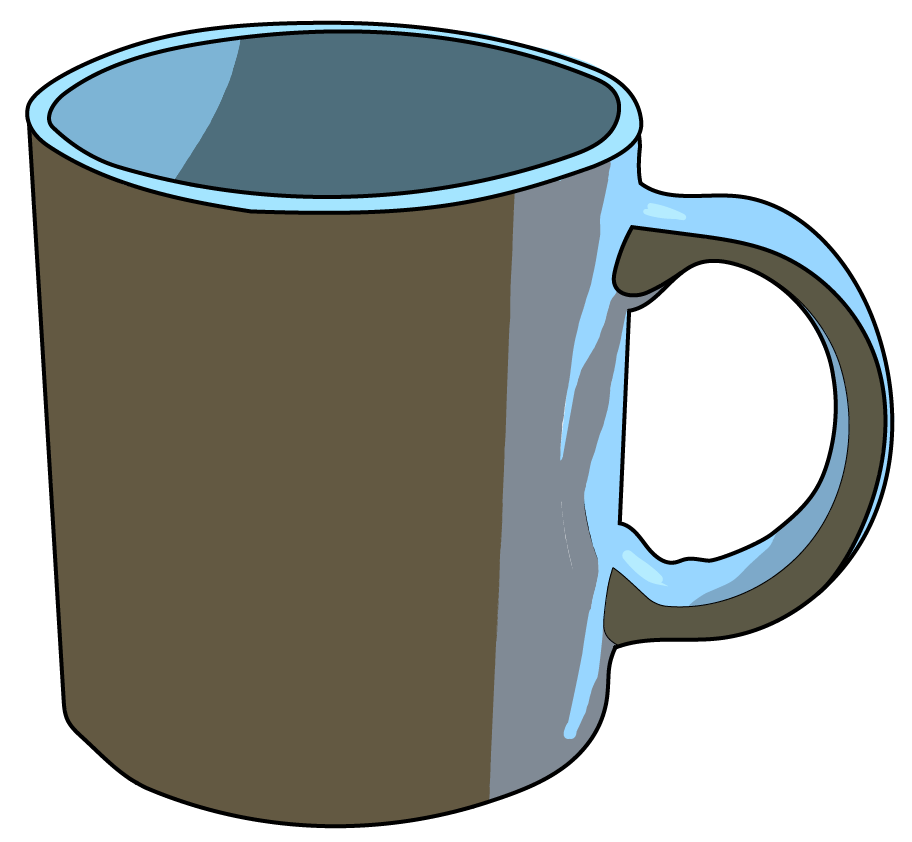             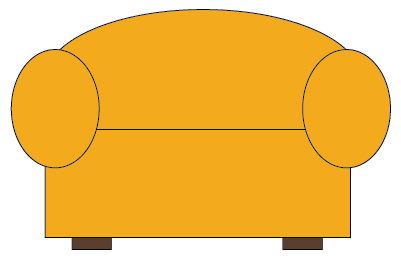            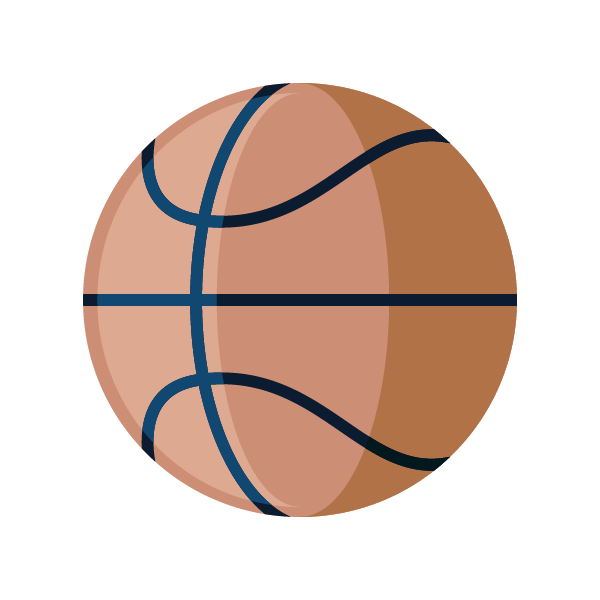

 Las derivadas nos permiten responder estas preguntas calculando tasas de cambio para una función determinada. 

** Antes de comenzar: **

 Este script en vivo está diseñado para usarse con el código oculto. En la pestaña ** Ver ** de la barra de herramientas de MATLAB, en la sección ** Ver **, seleccione ** Ocultar código **. Alternativamente, seleccione ** Ocultar código ** usando el ícono   en la parte superior derecha del panel Live Editor. 

 Aunque el código está oculto, cierta interactividad requiere familiaridad con MATLAB. Si necesita más instrucción, considere realizar [Rampa de entrada de MATLAB](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), un tutorial en línea gratuito de 2 horas que enseña los conceptos básicos de MATLAB. 

 Para una experiencia óptima, siga las instrucciones y pasos en la secuencia indicada. Pase a una nueva sección sólo después de completar la anterior. Algunas secciones dependen de variables creadas en secciones anteriores y generarán errores si se agotan. 

 Los íconos   y  se refieren a dos tipos diferentes de actividades interactivas que encontrará en este script. El   generalmente indica una interacción en la que explorará la visualización de algún concepto introducido en este script. Las interacciones  están diseñadas para desafiar su comprensión de esos conceptos y su profesor puede utilizarlas para calificar y verificar la finalización. 

##  Definición de la derivada 

 La derivada de una función sigue la tasa de cambio de esa función en cada punto de su dominio. 

####  Ejemplo motivador: enfriar café 

 Considere la función $T(t)$ que rastrea la temperatura, en grados Celsius, de una taza de café en función del tiempo, en minutos. Si el café se sirve de una jarra con temperatura controlada mantenida a $95^{\circ}$ C durante $t=5$ minutos, a continuación se presenta una curva de enfriamiento representativa. La tasa de cambio de $T(t)$ con respecto al tiempo $t$ en este escenario es la tasa a la que se enfría el café, con unidades de grados Celsius por minuto. Cálculo proporciona herramientas que pueden determinar la tasa de cambio en cada punto de esta función. 

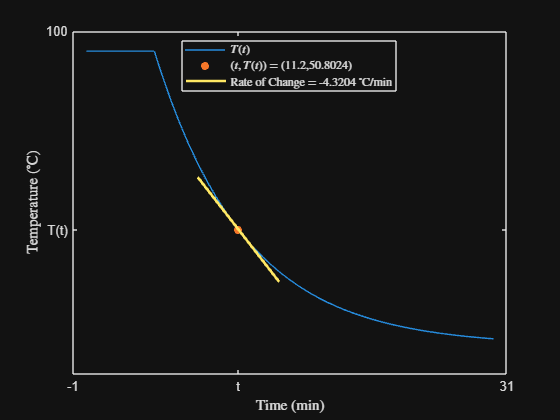

t1 = 11.2;   % Seleccione un punto para evaluar T(t), por defecto t1 = 6 
dx = 3;     % radio de la recta tangente a dibujar
                   % Ejecute esta sección
if ~exist("sCoffee","var")||~isvalid(sCoffee)
    syms t;       % Crear una variable simbólica
    % Ejecute la función CoffeeExample, definida en Funciones auxiliares locales
    [sCoffee,tHandle,Temp] = CoffeeExample(t1,dx); 
    ax = sCoffee.Parent;           % Sigue el eje que traza la curva del café.
else
sCoffee.XData = t1;    % Restablecer el cinturón de coordenadas x del punto
T1 = double(Temp(t1)); % Evaluar el punto T1 = T(t1)
sCoffee.YData = T1;    % Restablecer la coordenada y del punto  
tHandle.XData = [t1-dx,t1+dx];     % Restablecer los datos x para la aproximación lineal
[m,TempVals] = GetLinApprox(Temp,t,t1,T1,dx);   % La función GetLin Aprox está definida en Funciones auxiliares locales.
tHandle.YData = TempVals;  % Restablecer los datos y para la aproximación lineal
xticks(ax,[-1 t1 31]);     % Agregue una marca x en el punto t=x1
yticks(ax,[15 T1 100]);    % Agregue una marca y en el punto T=T1
legend(ax,["$T(t)$" "$(t,T(t))$ = ("+t1+","+T1+")" "Rate of Change " + ...
    "= "+m+" $^{\circ}$C/min"],"Location","best","Interpreter","latex")
drawnow
end

####  Ejemplo motivador: Baloncesto 

 La altura de una pelota de baloncesto $H$ , en metros, en función del tiempo $t$ , en segundos, tiene una derivada que sigue la tasa de cambio de altura con respecto al tiempo en metros por segundo. La derivada de una función de posición con respecto al tiempo es una función de velocidad. La derivada de una función de velocidad con respecto al tiempo es una función de aceleración. 

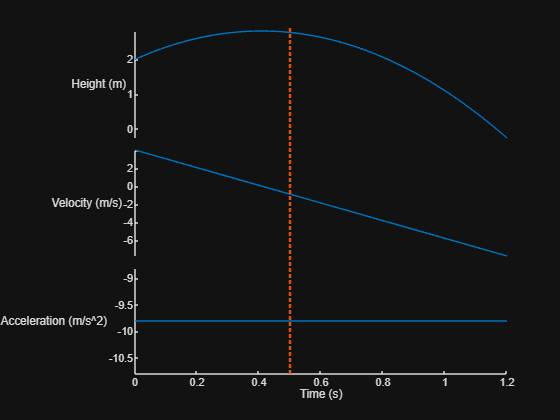

t2 = 0.5;  % Seleccione el momento a considerar
               % Ejecute esta sección
if ~exist("lH","var") || ~isvalid(lH) 
                                  % Compruebe si esta sección se ha ejecutado antes; si no, configure el gráfico
    figure 
    lH = BasketballExample(t2);   % Ejecute la función BasketballExample que se encuentra en Funciones auxiliares locales
else
    xloc = .9061-.1331*(5-25/6*t2);   % Escale el valor de x para la línea a la ventana de trazado dentro de la ventana de la figura
    %xloc = 0.9061-0.149*(5-25/6*t2);
    lH.X = [xloc xloc];               % Actualizar la ubicación de la línea de puntos.
end

####  Ejemplo motivador: trasladar un sofá 

 Considere trasladar un sofá a un apartamento nuevo. Puede que sea necesario maniobrar el sofá alrededor de una esquina, pero los sofás no son flexibles. Cálculo ofrece herramientas para determinar si un sofá unidimensional cabe en una esquina. El cálculo proporciona un método que localizará el valor mínimo del camino más largo sobre todos los caminos posibles alrededor de una curva. Se podrían emplear métodos similares para un sofá tridimensional más realista. 

 Las líneas negras modelan las paredes, el área blanca es el piso disponible y la línea roja modela el sofá. 

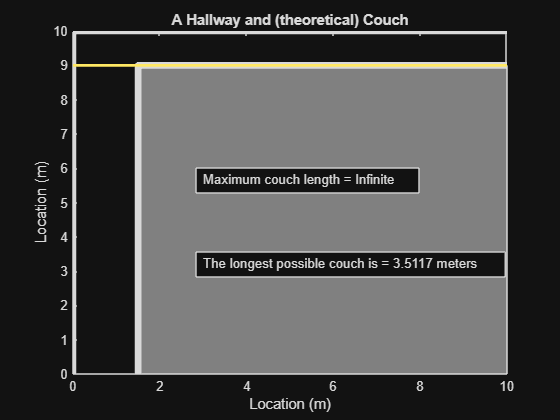

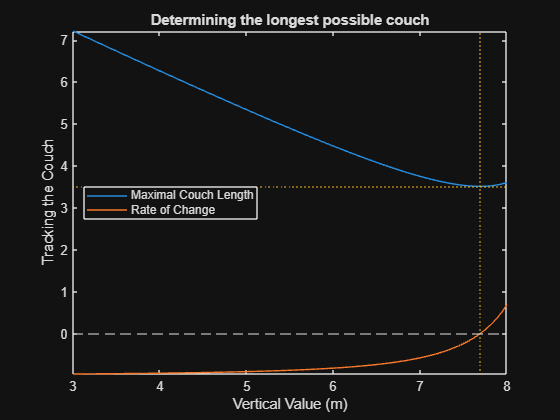

Observe the fact that the minimal value of the maximal couch length
occurs when the rate of change of the maximal couch length is 0.


           % Este botón ejecuta esta sección de código.
CouchExample([1.5 9]);  % Ejecute la función CouchExample que se encuentra en Funciones auxiliares locales

###  Definición límite de la derivada 

 Más formalmente, la derivada de una función $y=f(x)$ se define como el límite de las pendientes de las rectas secantes entre los puntos $(x,f(x))$ y $(x+h,f(x+h))$ : 


$$f'(x) = \lim_{h \rightarrow0} \enspace\frac{f(x+h) - f(x)}{h}$$
 

####  Ejemplo ilustrativo 

 Sea $f(x) = x^2$ , y elija un valor particular $x_1=-1$ y comience con $h=2.5$. Observa la pendiente de la recta secante a medida que haces $|h|$ más pequeño. 

syms x            % Configurar una variable simbólica x
f(x) = x^2;       % Definir una función f(x) = x^2
x1 = -1;          % Establezca el valor inicial x=x1 en -1
h = 2.5;     % Seleccione el tamaño del paso h
figure
 
fplot(f(x))       % Trazar la función y=f(x) usando el comando de trazado de función simbólica
hold on
title("Plotting the secant line between $x = $" + x1 + " and $x+h = $" + x1+h,"Interpreter","latex")
xlabel("x")
ylabel("f(x)")
GraphSecant(@(x)f(x),x1,x1+h,"f");         % GraphSecant es una función en funciones auxiliares locales
legend(["" "$f(x)$" "Secant line from $x_1$ to $x_1+h$"],"Location","north")
m = double((f(x1+h)-f(x1))/(h));           % Calcular la pendiente de la recta secante
annotation("textbox",[.4 .5 .2 .2],"EdgeColor","none","String","slope = "+m) % Mostrar la pendiente en el gráfico.


$$\text{Slope}  = \frac{f(-1+h)-f(-1)}{h} = \frac{(-1+h)^2-(-1)^2}{h} = \frac{1-2h+h^2-1}{h} = -2+h$$


 La derivada de la función $f(x)$ en el punto $x=x_1$ es 


$$f'(x_1) = \lim_{h\to 0} \frac{f(x_1+h)-f(x_1)}{h} = \lim_{h\to 0} -2 + h = -2$$


fplot(f(x))           % Trazar y=f(x) usando la función gráfica simbólica
dx = 0;               % Establezca un tamaño de paso de 0 para reutilizar el código secante para graficar una línea tangente
hold on
title("Plotting the tangent line to $f(x) = x^2$ at $x_1 =$" + x1,"Interpreter","latex")
xlabel("x")
ylabel("f(x)")
GraphSecant(@(x)f(x),x1,x1+dx,"f");  % GraphSecant se define en funciones auxiliares locales
hold on
scatter([x1 x1+dx],double([f(x1) f(x1+dx)]),"o","filled","SeriesIndex",2)    % Trazar (x1,f(x1))
legend(["" "$f(x)$" "Tangent line at $x_1$"],"Location","north","Interpreter","latex")
m = 2*x1;            % Calcula la pendiente de la recta tangente a x^2 en x=x1
annotation("textbox",[.4 .5 .2 .2],"EdgeColor","none","String","slope = "+m) % Mostrar la pendiente en el gráfico.
hold off

 La recta que pasa por un punto de una curva con una pendiente igual a la derivada en ese punto se llama recta tangente. Es la mejor aproximación lineal a la función en ese punto. 

 Poniendo todo esto junto: 


$$f'(x) = \lim_{h \rightarrow0} \enspace\frac{f(x+h) - f(x)}{h}= \lim_{\Delta x \to 0} \frac{\Delta f}{\Delta x} = \lim_{(x_2-x_1) \to 0} ~\frac{y_2 - y_1}{x_2-x_1}$$


 La razón $\frac{f(x+h)-f(x)}{h}$ se llama cociente de diferencias. 

###  Derivadas como límites de rectas secantes 

  ** Pruebe. **

 Primero, utilice la función predeterminada para configurar una representación gráfica de la definición del límite. Luego pruebe algunas funciones más de su elección. 

syms x f(x) h df dx              % configurar variables y funciones simbólicas
f(x) =  x^3      % definir la función y mostrar el resultado

  ** Consejo profesional **. La sintaxis de MATLAB es `3*x^2` para $3x^2$ o `exp(2*x)` para $e^{2x}$. Para obtener más detalles, consulte la documentación del Centro de ayuda para [funciones matemáticas](https://www.mathworks.com/help/matlab/referencelist.html?type=function&listtype=cat&category=mathematics) o [Referencia de funciones básicas](https://www.mathworks.com/content/dam/mathworks/fact-sheet/matlab-basic-functions-reference.pdf). 

                 % Ejecute la sección actual
figure                            % Inicializar una figura
x1 = 1;  % Definir un valor para x1
fx1 = f(x1);                      % Calcular el valor f(x1)
x2 = -4; % Definir un valor para x2
                                  % out es verdadero si x1-x2 = 0
out = GraphSecant(@(x) f(x),x1,x2,"f");  % GraphSecant se define en funciones auxiliares
if out                            % Ejecute si x1-x2 = 0 para resaltar la diferencia secante/tangente
    warning("There is no secant line through a single point. Graphing the tangent line.")
end

** Cálculos: **

 Utilice $h$`=x2-x1` para el tamaño de paso $\Delta x$ : 

deltax = x2-x1;    % Calcular h = x2-x1, el denominador del cociente de diferencias
% Imprimir los pasos del cálculo.
displayFormula("h = deltax")
if deltax ~= 0                       % Cálculos separados de secante y tangente
    fx2 = f(x2);                     % Calcular el valor f(x2)
    df21 = fx2-fx1;                  % Calcule f(x2)-f(x1), el numerador del cociente de diferencias
    sDQ = simplify(df21/deltax);     % Simplifica simbólicamente el cociente de diferencias.
    vpaDQ = vpa(sDQ);                % Expresar el cociente de diferencias en aritmética de precisión variable.
    displayFormula("f(x_1+h)-f(x_1) = f(x2)-f(x1)")
    displayFormula("f(x_1+h)-f(x_1) = fx2-fx1")
    displayFormula("(f(x_1+h)-f(x_1))/h = sDQ")
    if ~isequal(round(sDQ),sDQ)
        displayFormula("(f(x_1+h)-f(x_1))/h = vpaDQ")
    end
else
    fxph = f(x+h);                   % Nombra la expresión simbólica f(x+h)
    fx = f(x);                       % Nombra la expresión simbólica f(x)
    displayFormula("df/dx = limit((fxph-fx)/h,h,0)")
    dfEval(x) = diff(f(x),x);        % Calcular la derivada simbólica f'(x)
    dfxS = simplify(dfEval(x1));     % Evaluar y simplificar simbólicamente f'(x1)
    dfxV = vpa(dfxS);                % Expresar f'(x1) en aritmética de precisión variable
    displayFormula("df/dx = dfxV")
end

  ** Pruebe **

 Investigue qué sucede con diferentes valores de `x1` y `x2` y para diferentes funciones `f(x)`. 

 ** Reflexiona **

-  ¿Qué notas sobre la pendiente de la recta secante cuando cambias `x2` ? 

-  ¿Qué sucede cuando estableces `x2` igual a `x1`? 

-  ¿Puedes encontrar valores para `x1` y `x2` donde la recta secante tiene pendiente positiva? ¿O pendiente negativa? ¿O pendiente cero? 

-  ¿Cambian sus respuestas a la pregunta 3 si comienza con una función diferente `f(x)`? 

##  Las derivadas son pendientes 

 Utilizando el hecho de que la derivada es la pendiente de la recta tangente, intenta evaluar la definición de la derivada en diferentes puntos. Observe que cuando la derivada es positiva, la función es creciente (y viceversa). La función que está explorando aquí es $y = 6 + \cos(x) - \frac{32}{5}e^{-x/5}$ en un rango de $x=0$ a $x=25$. 

xPosn = 17;  % Establecer el valor de x a considerar
figure
ExampleFunction(xPosn,2); % La función de ejemplo se define en funciones auxiliares locales
                          % Ejecute esta sección

 ** Reflexiona **

-  ¿Qué notas sobre la derivada cerca de la cima de un pico? ¿Qué pasa cerca del fondo de un valle? 

-  ¿Puedes calcular la derivada de esta función a partir de su definición límite? ¿Por qué o por qué no? 

## ** Derivadas gráficas **

 Sorprendentemente a menudo, es suficiente conocer el signo (positivo, negativo o cero) de una derivada. Una derivada positiva en un punto significa que el valor de la función aumenta de izquierda a derecha en ese punto. Un valor negativo significa que el valor de la función está disminuyendo de izquierda a derecha en ese punto. Y una derivada cero significa que el valor de la función es constante, sin aumentar ni disminuir, en ese punto. 

syms x                            % Crea la variable simbólica x
g(x) =  exp(x)*cos(x)+x^2       % Definir una función g(x)
xa = -3;  % Seleccione un punto x=xa
                        % Ejecute esta sección de código
figure 
try
fplot(g,"SeriesIndex","none");    % Trazar simbólicamente la función y=g(x)
catch
    fplot(g,"k")
end
hold on
scatter(xa,g(xa),75,"filled","SeriesIndex",2)    % Trazar el punto (xa, g(xa))
hold off
title("Plot of $y = g(x)$ and the point $(x_1, g(x_1))$ = (" + xa + "," + double(g(xa)) + ")","Interpreter","latex")
xlabel("$x$","Interpreter","latex")
ylabel("$g(x)$","Interpreter","latex")

** Ejercicio 1 **. Determina el signo de la derivada en el punto que has seleccionado: 

slope = "undefined";       % Establecer el valor de la pendiente a partir de un conjunto de opciones
                         % Ejecute esta sección
if ~exist("xa","var")               % Comprobar si la variable xa existe
    xa = 3;                         % Si no, establezca xa en su valor predeterminado
end
if ~exist("g","var")                % Compruebe si la función g(x) existe
    syms x
    g(x) = exp(x)*cos(x)+x^2;       % Si no, establezca g(x) en su valor predeterminado
end
CheckSlope(slope,@(x) g(x),xa,"g"); % La función checkSlope está definida en Funciones auxiliares

** Ejercicio 2 **. Encuentra un punto en la gráfica que tenga la derivada especificada: 

                     % Ejecute esta sección
syms x                          % Crea la variable simbólica x
figure                          % Inicializar una figura
q(x) = piecewise( ...           % Definir una función por partes q(x)
    x < -1, 5-(x+3)^2, ...      % si x < -1, q(x) = 5-(x+3)^2
    x < 2, -x, ...              % si -1 <= x < 2, q(x) = -x
    x < 4, -2, ...              % si -2 <= x < 4, q(x) = -2
    (x-4)^3-2);                 % si x >= 4, q(x) = (x-4)^3-2
p = fplot(q(x),"LineWidth",1);  % Trazar simbólicamente la función y=q(x)
ylim([-3 6])                    % Establezca los límites de y para contener estrictamente los valores máximo y mínimo de y=q(x)
xticks(-5:5)                    % Mostrar x ticks en cada valor entero
xlabel("x")
ylabel("y")
title("Graph for Exercise 2")
grid on                         % Active la cuadrícula para permitir un fácil análisis del gráfico.

 Identifica cada punto por su valor `x`. 

 1. Identifica un punto con `x<0` donde la derivada es positiva. 

q1 = -6;     % Solicitar la entrada del usuario como x = q1
if (q1 < -5) || (q1 > 5)       % Compruebe si q1 no está en el dominio definido, [-5,5]
    disp("Please select a value between -5 and 5.")
elseif (q1 > -5) && (q1 < -3)  % Compruebe si q1 está en (-5,-3)
    disp("Correct.")
elseif q1 == -5                % Compruebe si q1 está en el límite
    disp("You cannot be sure what the derivative is at the boundary of a plot without additional information.")
elseif q1 > 4                  % Compruebe si q1 es positivo y está en una región con derivada positiva
    disp("This is not a point with x<0.")
else                           % Respuesta general incorrecta
    disp("Incorrect. Please try again.")
end

 2. Identifica un punto con `x>0` donde la derivada es positiva. 

q2 = 6;     % Solicitar la entrada del usuario como x = q2
if (q2 < -5) || (q2 > 5)       % Compruebe si q2 no está en el dominio definido, [-5,5]
    disp("Please select a value between -5 and 5.")
elseif (q2 > -5) && (q2 < -3)  % Compruebe si q2 es negativo y está en una región con derivada positiva
    disp("This is not a point with x>0.")
elseif q2 == 5                 % Compruebe si q2 está en el límite
    disp("You cannot be sure what the derivative is at the boundary of a plot without additional information.")
elseif q2 > 4                  % Comprueba si q2 está en (4,5)
    disp("Correct.")
else                           % Respuesta general incorrecta
    disp("Incorrect. Please try again.")
end

 3. Identifica un punto con `x<0` donde la derivada es negativa. 

q3 = -6;     % Solicitar la entrada del usuario como x = q3
if (q3 < -5) || (q3 > 5)       % Compruebe si q3 no está en el dominio definido, [-5,5]
    disp("Please select a value between -5 and 5.")
elseif (q3 > -3) && (q3 < 0) && (q3 ~= -1)  
                               % Compruebe si q3 es negativo y está en una región con derivada negativa
    disp("Correct.")
elseif q3 == -1                % Comprobar si q3 es un punto crítico
    disp("The derivative does not exist at this point. Please try again.")
elseif (q3 >= 0) && (q3 < 2)   % Compruebe si q3 es positivo y está en una región con derivada negativa
    disp("This is not a point with x<0.")
else                           % Respuesta general incorrecta
    disp("Incorrect. Please try again.")
end

 4. Identifica un punto con `x>0` donde la derivada es negativa. 

q4 = 6;         % Solicitar entrada del usuario como x = q4
if (q4 < -5) || (q4 > 5)           % Compruebe si q4 no está en el dominio definido, [-5,5]
    disp("Please select a value between -5 and 5.")
elseif (q4 > 0) && (q4 < 2)        % Compruebe si q4 es positivo y está en una región con derivada negativa
    disp("Correct.")
elseif (q4 > -3) && (q4 <= 0) && (q4 ~= -1)  
                                   % Compruebe si q4 es negativo y está en una región con derivada negativa
    disp("This is not a point with x>0.")
else                               % Respuesta general incorrecta
    disp("Incorrect. Please try again.")
end

 5. Identifica un punto con `x<0` donde la derivada es cero. 

q5 = -6;    % Solicitar entrada del usuario como x = q5
if (q5 < -5) || (q5 > 5)      % Compruebe si q5 no está en el dominio definido, [-5,5]
    disp("Please select a value between -5 and 5.")
elseif q5 == -3               % Compruebe si q5 es un extremo
    disp("Correct.")
elseif (q5 > 2) && (q5 <= 4)  % Compruebe si q5 es positivo y está en una región donde la derivada es cero
    disp("This is not a point with x<0.")
else                          % Respuesta general incorrecta
    disp("Incorrect. Please try again.")
end

 6. Identifica un punto con `x>0` donde la derivada es cero. 

q6 = 6;    % Solicitar entrada del usuario como x = q6
if (q6 < -5) || (q6 > 5)      % Compruebe si q6 no está en el dominio definido, [-5,5]
    disp("Please select a value between -5 and 5.")
elseif (q6 > 2) && (q6 <= 4)  % Compruebe si q6 es positivo y está en una región con derivada 0
    disp("Correct.")
elseif q6 == -3               % Compruebe si q6 es negativo y tiene derivada 0
    disp("This is not a point with x>0.")
else                          % Respuesta general incorrecta
    disp("Incorrect. Please try again.")
end

 7. Identifica dos puntos diferentes, `x1` y `x2` en el intervalo (-5,5), donde la derivada no existe. 

q71 = -6;                                  % Solicitar entrada del usuario como x = q71
q72 = 6;                                  % y x = q72
if (q71 < -5) || (q71 > 5) || (q72 < -5) || (q72 > 5)        % Compruebe si los valores están en el dominio definido.
    disp("Please select values between -5 and 5.")
elseif (q71 == -1 && q72 == 2) || (q71 == 2 && q72 == -1)    % Comprueba si los valores son correctos.
    disp("Correct.")
elseif (q71 == -1) || (q72 == -1)                            % Compruebe si solo se ha encontrado un valor correcto
    disp("Yes, the derivative does not exist at the point x = -1, but what about the second point?")
elseif (q71 == 2) || (q72 == 2)                              % Compruebe si solo se ha encontrado un valor correcto
    disp("Yes, the derivative does not exist at the point x = 2, but what about the second point?")
else                                                         % Respuesta general incorrecta
    disp("Incorrect. Please try again.")
end
  % Ejecute esta sección to generate feedback on all the solutions at once, all default answers are outside [-5,5]

 ** Reflexiona **

-  ¿Qué tan fácil es encontrar puntos donde la derivada es cero? ¿Existen en su gráfico? ¿Por qué o por qué no? 

-  ¿Qué te dice sobre tu función conocer el signo de la derivada? 

-  Usando + para regiones con derivada positiva, - para regiones con derivada negativa y 0 para regiones donde la derivada es cero, ¿puedes esbozar dos o más funciones con derivadas que se ajusten a patrones diferentes? ¿Qué tal + en todas partes? ¿O -0+? ¿O +0-0+? ¿Quizás -0-? 

-  ¿Puedes dibujar una función con una derivada que sea -+ y nunca 0? ¿Por qué o por qué no? 

####  Derivada como operador 

 La derivada puede considerarse como un operador $\frac{d}{dx}$ que actúa sobre una función $f(x)
$ usándola para producir una nueva función $\frac{df}{dx}$ que sigue la tasa de cambio de la función original en cada punto. Alternativamente, puedes pensar en la derivada como una caja negra que acepta una función como entrada y devuelve una función nueva, pero relacionada, como salida, similar a algunas visualizaciones de funciones mismas: 

 Para una función, la entrada $x$ se transforma a una salida $f(x)$ : 

 Para una derivada, la entrada $f(x)$ se transforma en una salida $\frac{df}{dx}$ que también se puede escribir como $f'(x)$ : 

 

##  Notas sobre la notación 

 Es posible que veas la derivada de una función representada usando diferentes notación. 

 Notación:                          Lectura como: 

         $f'(x)$ "eff prime of ex", 

           $\frac{df}{dx}$ "dee eff dee ex", 

             $\frac{d}{dx}[f(x)]$ "dee dee ex of eff of ex", 

 Si bien pueden parecer diferentes, todos estos las notaciones significan lo mismo: la derivada de una función $f(x)$ con respecto a la variable $x$. 

 Aunque para este ejemplo se eligieron las funciones f y x, ¡puedes extender esta notación a cualquier función y variable! Por ejemplo, la derivada de la función g con respecto a la variable z (en sus notaciones correspondientes a lo anterior) se vería así: 


$$g'(z), \enspace \frac{dg}{dz},\enspace\frac{d}{dz}[g(z)]$$


 Hay una sutil diferencia en la notación entre $f'(x), \enspace \frac{df}{dx} \enspace$ y $\frac{d}{dx}[f(x)]$. Los primeros describen funciones que son el resultado de aplicar el operador derivada a una función. La notación $f'(x)$ se llama "notación prima" y se usa principalmente como abreviatura cuando solo hay una variable independiente y especialmente cuando la derivada se va a evaluar en puntos específicos, como $f'(a)$ para describir la pendiente de la función $f(x)$ en el punto $x=a$. Este último hace referencia al acto de tomar la derivada de una función. En este sentido, la última notación se refiere a la derivada como un "operador" donde "opera/actúa" sobre la función original. 

[⇦ Volver al menú principal](matlab:open('MainMenu.mlx'))

##  Funciones auxiliares locales 

 Si desea ver los detalles del código, seleccione la pestaña ** Ver ** y cambie a ** Salida en línea **. Como alternativa, seleccione ** Salida en línea ** usando el ícono   en la parte superior derecha del panel Live Editor. 

function [sP,cTan,T] = CoffeeExample(x1,dx)
% Este ejemplo crea el gráfico del ejemplo del café enfriado
% T(t) se definió usando la ley de enfriamiento de Newton aplicada a un líquido almacenado en un ambiente con temperatura controlada de 95 grados
% hasta t = 5, luego Se trasladó a un ambiente
% con temperatura controlada de 22 grados y se dejó que se equilibrara. La constante de tiempo se estimó
% para aproximarse a la experiencia del autor.
syms t      % Configurar la variable simbólica t
T(t) = piecewise(t<5,95,73*exp(-.15*(t-5))+22);  % Defina la función de temperatura simbólica por partes T(t)
y1 = double(T(x1));  % Calcular T(x1) como un número
[m,linApprox] = GetLinApprox(T,t,x1,y1,dx);  
fplot(T,[0 30]);   % Trazar simbólicamente la temperatura durante 30 minutos.
hold on
sP = scatter(x1,y1,"filled","SeriesIndex",2); % Añade un punto en (x1,T(x1))
cTan = plot([x1-dx,x1+dx],linApprox,"LineWidth",2,"SeriesIndex",3); % Linea tangente
hold off
ylim([15 100])             % Elija límites y para una ventana de visualización razonable
xlim([-1 31])              % Elija x límites para una ventana de visualización razonable
xlabel("Time (min)","Interpreter","latex")
ylabel("Temperature ($^{\circ}$C)","Interpreter","latex")
xticks([-1 x1 31]);       % Agregue una marca x en el punto t=x1
yticks([15 y1 100]);      % Agregue una marca y en el punto T=y1
xticklabels(["-1" "t" "31"])
yticklabels(["15" "T(t)" "100"])
legend(["$T(t)$" "$(t,T(t))$ = (" + x1 + "," + y1 + ")" "Rate of Change = " ...
    + m + " $^{\circ}$C/min"],"Location","best","Interpreter","latex")
end

function [m,LinApproxVals] = GetLinApprox(y,x,a,ya,dx)
% GetLin Aprox calcula la recta tangente a y en x=a
%
% GetLin Aprox requiere cuatro argumentos
% y una función simbólica
% x la variable independiente simbólica
% a el punto de tangencia como un doble
% ya el valor y(a) como un doble
% dx el radio del intervalo deseado como doble
%
% GetLin Aprox devuelve dos valores
% m es la pendiente doble
% Lin AproxVals es un vector de valores de la aproximación lineal en a-dx y a+dx

dy = diff(y,x);           % Calcular simbólicamente la derivada y'(x)
m = double(subs(dy,x,a)); % Evaluar la pendiente m = y'(a)
LinApproxVals = ya+m*([-dx dx]);  % Calcular dos puntos en la recta tangente.
end

function lH = BasketballExample(xpt)
% Cree un ejemplo de baloncesto que presente la relación entre
% pendientes/derivadas/tasas de cambio y las curvas de posición, velocidad y
% aceleración.
%
% BasketballExample toma una entrada, t=xpt
v0 = 4;             % Seleccione valores realistas para la velocidad inicial (m/s)
h0 = 2;             % Seleccione valores realistas para la altura inicial (m)
tVals = 0:.01:1.2;  % Configurar un vector de valores de tiempo
hVals = h0-9.81/2*tVals.*tVals+v0*tVals; % Calcular h = -9,81/2*t^2+v0*t+h0 (m)
vVals = -9.81*tVals+v0;                  % Calcular v = -9,81*t+v0 (m/s)
aVals = -9.81*ones(size(tVals));         % Calcular a = -9,81 (m/s^2)
yVals = [hVals' vVals' aVals'];          % Combinar en una sola matriz con vectores de columna h,v,a
% Se utilizó un gráfico apilado para representar gráficamente y=h, y=v e y=a en los mismos ejes de entrada.
stackedplot(tVals,yVals,"DisplayLabels",["Height (m)" "Velocity (m/s)" "Acceleration (m/s^2)"]);
xlabel("Time (s)")
xloc = .9061-0.149*(5-25/6*xpt);   % Escale el valor de x para la línea a la ventana de trazado dentro de la ventana de la figura
% xloc = .9061-.1331*(5-xpt); % Escale el valor de x para la línea a la ventana de trazado dentro de la ventana de la figura
cdata = colororder;
lH = annotation("line",[xloc xloc],[.1100 .9350],"LineStyle",":","Color",cdata(2,:),"LineWidth",2); % Agregar línea de puntos
end

function shortest = CouchExample(corner)
% CouchExample anima el problema de minimización de una longitud que pasa alrededor de
% una esquina. Los parámetros actuales no generan un conjunto de restricciones
% particularmente estricto.
%
% CouchExample toma un argumento
% corner=[a,b] con 0 < a,b < 10 ubicando una esquina
% CouchExample devuelve un valor
% el más corto es la longitud máxima mínima de una recta línea desde un pasillo
% pared a la otra
try
    p = plot([0 0 10],[0 10 10],"-","LineWidth",5,"SeriesIndex","none"); % Trazar la línea de la pared exterior
catch
    p = plot([0 0 10],[0 10 10],"k-","LineWidth",5)
end
hold on
% Sombrea el espacio inaccesible en la esquina inferior derecha de la trama.
rectangle("Position",[corner(1) 0 10-corner(1) corner(2)],"FaceColor",[.5 .5 .5])
% Trazar la línea de la pared interior.
try
    plot([corner(1) corner(1) 10],[0 corner(2) corner(2)],"-","LineWidth",5,"SeriesIndex","none")
catch
    plot([corner(1) corner(1) 10],[0 corner(2) corner(2)],"k-","LineWidth",5)
end
xlabel("Location (m)")
ylabel("Location (m)")
title("A Hallway and (theoretical) Couch")
% Cree la línea que modela el sofá desde un punto en la pared exterior izquierda
% (0,cy) a través de la esquina y extendiéndose hasta la pared exterior superior
% Es un objeto de trama para facilitar la animación. restableciendo solo sus valores
% en lugar de volver a dibujar todo el gráfico en cada iteración
couch = plot([0 (10*corner(1))/corner(2)],[0 10],"-","LineWidth",2,"SeriesIndex",3);
% Utilice la fórmula de la distancia para determinar la longitud de la línea del sofá.
maxCouchLength = sqrt((10/corner(2))^2 + (10-0)^2);
% Anota el gráfico con la longitud actual de la línea del sofá
% Crea un objeto de anotación para facilitar la animación restableciendo solo su valor de cadena
% en cada iteración del bucle siguiente
noteMaxLength = annotation("textbox",[.35,.4,.4,.2], ...
    "String","Maximum couch length = " + maxCouchLength,"EdgeColor",[.8 .8 .8], ...
    "BackgroundColor",p.Parent.Color,"FitBoxToText","on");
drawnow  % Forzar el dibujo de la trama en este punto.
% Recorra los valores de cy de 0 a 8,9 con tamaños de paso de 0,1 m.
for cy=0:.1:8.9
    m = (corner(2)-cy)/corner(1);       % Calcula la pendiente de la línea del sofá.
    % Termine la línea de sofás en la pared exterior superior o en el borde de la parcela.
    xLargest = min([(10-cy)/m 10]); % Determinar el valor x más grande
    if xLargest == 10  % Esto calcula el valor de y cuando el borde derecho de la trama es el punto final
        yLargest = m*10 + cy;
    else               % Esto calcula el valor de y cuando la pared exterior superior es el punto final
        yLargest = 10;
    end
    couch.XData = [0 xLargest];  % Establecer los valores del punto final x de la línea del sofá
    couch.YData = [cy yLargest]; % Establecer los valores del punto final y de la línea del sofá
    length = sqrt(((10-cy)/m)^2+(10-cy)^2); % Calcula la longitud de la línea del sofá.
    noteMaxLength.String = "Maximum couch length = " + length; % Establecer la cadena de anotación
    drawnow % Forzar dibujo de la nueva línea del sofá y anotación.
    hold off
end
% Cree la iteración final cuando el sofá esté paralelo a la pared exterior superior
% y anote el trazado en consecuencia.
hold on
couch.XData = [0 10];
couch.YData = [corner(2) corner(2)];
noteMaxLength.String = "Maximum couch length = Infinite";
drawnow
hold off
% Calcula simbólicamente la longitud máxima del sofá.
syms y        % Crear una variable simbólica y
% Cree una función simbólica que devuelva la longitud del sofá como una función
% de la posición y de la esquina (0,y)
L(y) = sqrt(((corner(1)*(10-y))/(corner(2)-y))^2+(10-y)^2);
dL = diff(L,y);               % Diferenciar simbólicamente para encontrar L'(y)
minY = vpasolve(dL,sym("y")); % Resuelva L'(y) = 0 y llame a esta solución minY
shortest = double(L(minY));   % Expresar L(minY) como un número
% subtitle("El sofá más largo posible es " + el más corto + " metros")
hold on
annotation("textbox",[.35,.2,.4,.2], ...
    "String","The longest possible couch is = " + shortest + " meters","EdgeColor",[.8 .8 .8], ...
    "BackgroundColor",p.Parent.Color,"FitBoxToText","on");
hold off
figure
fplot(L,[3 8])   % Trace simbólicamente la función L(y) en el intervalo [3,8]
hold on
fplot(dL,[3 8])  % Trace simbólicamente la derivada L'(y) en el intervalo [3,8]
cdata = colororder;
xline(double(minY),":","Color",cdata(3,:))  % Agregue una línea vertical en el valor y = minY
yline(shortest,":","Color",cdata(3,:))      % Agregue una línea horizontal en el valor L = L(minY)
try
    yline(0,"--","SeriesIndex","none")  % Agregue una línea que indique L'(y) = 0
catch
    yline(0,"k--")
end
title("Determining the longest possible couch")
xlabel("Vertical Value (m)")
ylabel("Tracking the Couch")
legend(["Maximal Couch Length" "Rate of Change"],"Location","west")
hold off
% Comentario para dirigir la atención a características interesantes de la trama.
disp("Observe the fact that the minimal value of the maximal couch length")
disp("occurs when the rate of change of the maximal couch length is 0.")
end

function out = GraphSecant(fh,x1,x2,fstr)
% GraphSecant traza una curva y=fh(x) y una recta secante entre
% dos puntos distintos (x1, fh(x1)) y (x2, fh(x2)) o la tangente
% a fh(x) en x=x1. Devuelve un valor lógico.
%
% GraphSecant requiere cuatro argumentos
% fh un identificador de función
% x1 un número
% x2 un número
% fstr una cadena de función, por ejemplo, "f"
% GraphSecant devuelve un valor
% la salida es lógica y es 1 si x1=x2 y 0 si x1 ~= x2
out = (x1 == x2);  % Esto es 1 para rectas tangentes y 0 para rectas secantes.
syms x;        % Crear una variable simbólica x
f(x) = fh(x);  % Defina una función f(x) desde el identificador de función fh
if x2 ~= x1    % Si x2 no es igual a x1, cree una función de línea secante
    secant(x) = f(x1) + (f(x2)-f(x1))/(x2-x1)*(x-x1);
else           % Si x2 = x1, crea una función de línea tangente
    df = diff(f);  % Calcular la derivada simbólica df=f'(x)
    secant(x) = f(x1) + df(x1)*(x-x1);
end
ax = gca;
fplot(f(x),Color=ax.GridColor) % Trazar simbólicamente y=f(x)
hold on
fplot(secant(x),"--","SeriesIndex",1) % Trazar simbólicamente la recta secante/tangente y=secante(x)
scatter(x1,f(x1),"Filled","SeriesIndex",2) % Suma el punto (x1,f(x1))
scatter(x2,f(x2),"Filled","SeriesIndex",2) % Suma el punto (x2,f(x2))

% Este código funciona para mejorar la legibilidad de la trama al rediseñar cómo se etiquetan las marcas
% a medida que se acercan.
ax = gca;      % Identificar un identificador para el objeto de ejes actual
NoTickOverlaps(x1,x2,"x1","x1+h",ax,"x","horiz") % Esta función está en Funciones auxiliares.
y2 = double(simplify(f(x2)));  % Expresar f(x2) como un número
y1 = double(simplify(f(x1)));  % Expresar f(x1) como un número
% Tenga en cuenta que fstr es una cadena pasada que nombra la función.
NoTickOverlaps(y1,y2,fstr+"(x1)",fstr+"(x1+h)",ax,"y","vert") % Esta función está en Funciones auxiliares.

% Etiqueta la trama con leyendas y títulos apropiados.
if x1 == x2
    legend([fstr+"(x)","Tangent line at $x_1$"],"Location","best","Interpreter","latex")
else
    legend([fstr+"(x)","Secant line from $x_1$ to $x_1+h$"],"Location"," best","Interpreter","latex")
end
hold off
formatStr = "$y = %s(x)$";           % Create a LaTeX format string for y=?(x)
fStringL = compose(formatStr,fstr);  % Cree la cadena LaTeX reemplazando ? con fstr
if out
    title("Plot of " + fStringL + " and the tangent line through (" + x1 + "," + double(f(x1)) + ")","Interpreter","latex")
else
    title("Plot of " + fStringL + " and the secant line between (" + x1 + "," + double(f(x1)) + ") and (" + x2 + "," + double(f(x2)) + ")","Interpreter","latex")
end
end

function NoTickOverlaps(y1,y2,str1,str2,ax,var,opt)
% y1, y2 son números, str1 y str2 son cadenas que etiquetan los puntos y1 y
% y2, ax es un identificador del eje de una figura y var es la variable de interés
% y opt es "vert " o "horiz" para elegir cómo mostrar las etiquetas
% superpuestas
switch var     % Utilice el eje apropiado
    case "x"
        valMinMax = ax.XLim;
        varLim = .05;   % Porque x+h es más largo que alto
    case "y"
        valMinMax = ax.YLim;
        varLim = .03;   % Un valor sólido para etiquetas de un solo carácter
    case "z"
        valMinMax = ax.ZLim;
end

varScale = valMinMax(2)-valMinMax(1); % Calcular la distancia total disponible

if y1 == y2
    % Si los valores son idénticos, solo se necesita una marca
    tickLocations = y1;
    formatStr = "%s = %s";
    labelStr = compose(formatStr,str1,str2);
    tickNames = labelStr;   % Esta es una etiqueta para un solo punto.
elseif 0< y2-y1 && (y2-y1)/varScale < varLim
    % If y2>y1, it should be above (vert) or to the right (horiz),
    % but not overlapping
    tickLocations = [y1 y2];
    if opt == "vert"
        % createStackedLabel está definido en Funciones auxiliares
        tickNames = CreateStackedLabel(str2,str1);
    elseif opt == "horiz"
        tickNames = [str1+str2 " "];
    end
elseif 0 < y1-y2 && (y1-y2)/varScale < varLim
    % If y2<y1, it should be below (vert) or to the left (horiz),
    % but not overlapping
    tickLocations = [y2 y1];
    if opt == "vert"
        % createStackedLabel está definido en Funciones auxiliares
        tickNames = CreateStackedLabel(str1,str2);
    elseif opt == "horiz"
        tickNames = [str2+str1 " "];
    end
elseif y1 < y2
    % Si y1 << y2, debería estar debajo (vert) o hacia la izquierda (horiz)
    tickLocations = [y1 y2];
    tickNames = [str1 str2];
else
    % Si y1 >> y2, debería estar arriba (vert) o a la derecha (horiz)
    tickLocations = [y2 y1];
    tickNames = [str2 str1];
end
switch var  % Etiqueta los ejes correctos
    case "x"
        ax.XTick = tickLocations;
        ax.XTickLabel = tickNames;
    case "y"
        ax.YTick = tickLocations;
        ax.YTickLabel = tickNames;
    case "z"
        ax.ZTick = tickLocations;
        ax.ZTickLabel = tickNames;
end
end

function strOut = CreateStackedLabel(top,bot)
% CreateStackedLabel toma dos cadenas y las refactoriza para
% Crear una etiqueta en blanco y una etiqueta apilada verticalmente para
% usar en NoTickOverlaps
row1 = [" " top];
row2 = [" " bot];
ylabelArray = [row1; row2];
ylabelArray = strjust(pad(ylabelArray,"left"));
strOut = sprintf("%s\\newline%s\n",ylabelArray{:});
end

function ExampleFunction(xPosn,dx)
% EjemploFunción toma un valor x = xPosn y un radio y traza 
% su ubicación en y = 6 + cos(x) - 32/5 * exp(-x/5) y calcula 
% e imprime su derivada *--- * y' de xPosn-dx a xPosn+dx también
syms x;                   % Crear variables simbólicas
y = 6 + cos(x) - 32/5 * exp(-x/5); % Definir y como una función simbólica de x
dy = diff(y);             % Calcular la derivada simbólica y'(x)
dyVal = double(subs(dy,x,xPosn)); % Evalúe y'(xPosn) simbólicamente
yVal = double(subs(y,x,xPosn));   % Evaluar y(xPosn) simbólicamente
xV = 0:.1:25;
yV = double(subs(y,xV));
plot(xV,yV);
hold on
plot([xPosn-dx xPosn+dx],[yVal-dyVal*dx yVal+dyVal*dx],"SeriesIndex",3)
% fplot(y,[0 25]) % Traza y simbólicamente para x en [0 25]
scatter(xPosn,yVal,"filled","SeriesIndex",2) % Añade el punto (xPosn,y(xPosn))
% Crea la cadena y anota la trama.
str = sprintf("$\\lim_{h \\rightarrow 0} \\enspace\\frac{f(%d+h) - f(%d)}{h}$ = %.2f",xPosn,xPosn,dyVal);
annotation("textbox",[.4 .35 .1 .1],"String",str,"FitBoxToText","on","Interpreter","latex","EdgeColor","w");
hold off
title("Compute the definition of the derivative")
end

function CheckSlope(slopeGuess,gh,xa,gstr)
% CheckSlope determina si la cadena pendienteGuess coincide con la pendiente real
% de la función definida por el identificador gh en el punto xa. Luego
% traza la función y la recta tangente en x=xa.
%
%     pendienteGuess es una cadena que es "positiva", "negativa" o "cero"
% gh es un identificador de función
% xa es un número
% gstr es una cadena que nombra la función
syms x;          % Crear una variable simbólica
g(x) = gh(x);    % Definir una función simbólica desde el identificador de función.
dg = diff(g,x);  % Calcular simbólicamente la derivada g'(x)
% Determinar la solución correcta.
slope = double(dg(xa));
if slope > 0
    CorrectSlope = "positive";
elseif slope < 0
    CorrectSlope = "negative";
else
    CorrectSlope = "zero";
end
% Compruebe si la solución definida por el usuario coincide con la solución correcta
% Luego muestre un mensaje apropiado
if slopeGuess=="undefined"
    disp("This is the default value. The slope is not undefined here. What is it?")
elseif (CorrectSlope == slopeGuess)
    disp("Correct. The slope at x = " + xa + " is " + slopeGuess + ".")
elseif abs(slope)<.1 
    disp("This might be frustrating, but the slope is not identically zero here. In fact, it is " + slope + " which is " + correctSlope + ".")
else
    disp("Incorrect. The slope at x = " + xa + " is " + slope + " which is " + CorrectSlope + ".")
end
% Grafica la función y la recta tangente en xa
GraphSecant(gh,xa,xa,gstr);
end 